% case1: P = 0
clear all
syms s

num = [1];
den = [1,2,1,0];
sys1 = tf(num,den);
sys2 = sys1*2;
sys3 = sys1*3

sys3 =
 
         3
  ---------------
  s^3 + 2 s^2 + s
 
연속시간 전달 함수입니다.
모델 속성


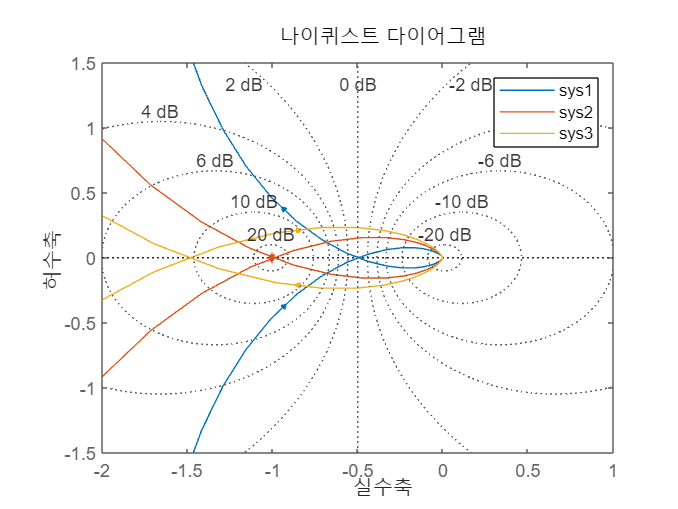


nyquist(sys1, sys2, sys3);
axis([-2, 1, -1.5, 1.5]);
legend('sys1','sys2','sys3')
grid on;

% case2: P != 0 (왼쪽에 있는 P)
clear all
syms s

num = [1];
den = [1, -1, 0];
sys1 = tf(num,den);
sys2 = sys1*2;
sys3 = sys1*3

sys3 =
 
     3
  -------
  s^2 - s
 
연속시간 전달 함수입니다.
모델 속성


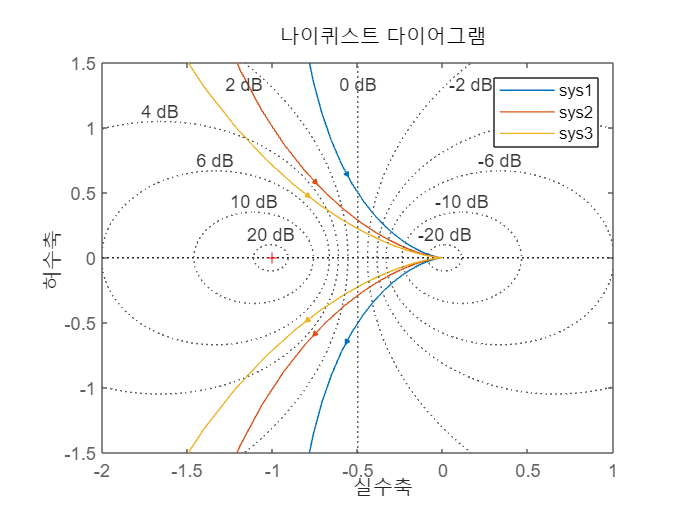


nyquist(sys1, sys2, sys3);
axis([-2, 1, -1.5, 1.5]);
legend('sys1','sys2','sys3')
grid on;

% case2: P != 0 (왼쪽에 있는 P)
clear all
syms s

num = [1, 1];
den = [1, -1, 0];
sys1 = tf(num,den);
sys2 = sys1*2;
sys3 = sys1*3

sys3 =
 
  3 s + 3
  -------
  s^2 - s
 
연속시간 전달 함수입니다.
모델 속성


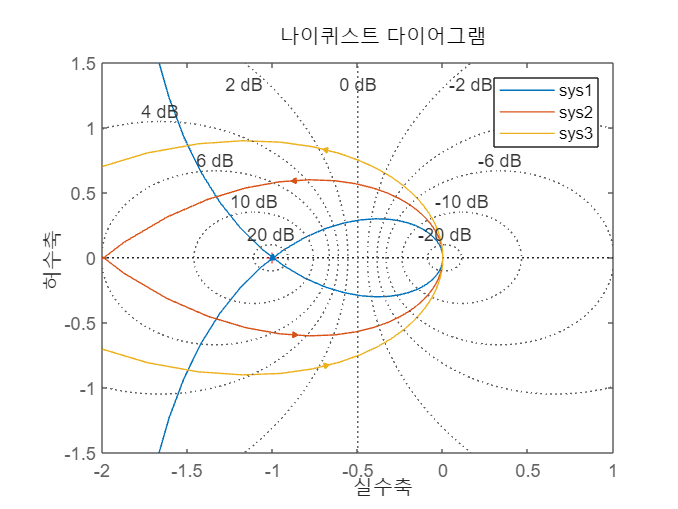


nyquist(sys1, sys2, sys3);
axis([-2, 1, -1.5, 1.5]);
legend('sys1','sys2','sys3')
grid on;